# Model wavefronts for DR01_54_HTI sample

**Author**: Abakumov Ivan

**Publication date**: 21st March 2018

**E-mail**: abakumov_ivan@mail.ru

## Introduction

`This script illustrates how to run FSM2DTTI eikonal solver`

## Define MLIB folder

%clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB/';
path(path, mlibfolder);
addmypath;

## Problem:

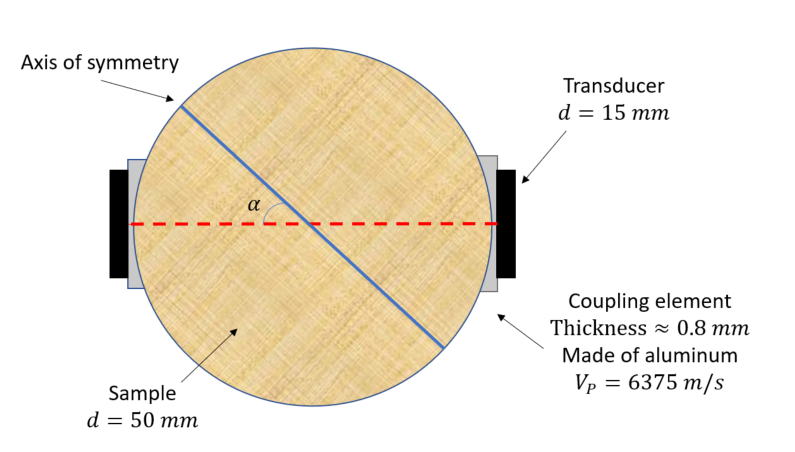

1) Model wavefronts as a function in the sample as a function of rotation angle

2) Model the effect of coupling element

3) Model the effect of Transducer on the recorded wavefield 

## Define grid

Create Grid file

For 2D codes only "x" and "z" fields are important

G=GridClass;

%    [mm]      [mm]       [mm]          [s]
G.x0=-27.5;  G.y0=0;    G.z0=-27.5;     G.t0 = 0.00;            % initial point
G.nx=1101;   G.ny=1;    G.nz=1101;      G.nt = 1000;             % grid size
G.dx=0.05;   G.dy=0;    G.dz=0.05;      G.dt = 0.01;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-27.5, dx=0.05, Nx=1101.
y0=0, dy=0, Ny=1.
z0=-27.5, dz=0.05, Nz=1101.
t0=0, dt=0.01, Nt=1000.


G.setGrid;

## Define velocity model

% Sample DR01-54-HTI
Sample.C11 = 63.3425*1e9; 
Sample.C33 = 51.9720*1e9;
Sample.C44 = 20.4813*1e9;
Sample.rho = 2507;
Sample.Vp0 = sqrt(Sample.C33/Sample.rho);
Sample.Vs0 = sqrt(Sample.C44/Sample.rho);
Sample.Epsilon = (Sample.C11 - Sample.C33)/(2*Sample.C33);
Sample.Delta = 0.124;
Sample.Theta = 0:5:90; 

Vqp = get_Vqp_VTI(Sample,Sample.Delta);


% sound
Vp      = 343*ones(G.nx,G.nz);  % speed of sound
Epsilon =   0*ones(G.nx,G.nz);
Delta   =   0*ones(G.nx,G.nz);
Alfa   =   0*ones(G.nx,G.nz);

% add aluminium coupling element
CE.minx = -26.8;   % 25 mm sample radius + 0.8 mm thickness of coupling element
CE.maxx =  26.8;         
CE.minz = -9;   % 12.5 mm coupling element radius
CE.maxz =  9;         
CE.gminx = x2grid(CE.minx,G.x0,G.dx,G.nx);
CE.gmaxx = x2grid(CE.maxx,G.x0,G.dx,G.nx);
CE.gminz = x2grid(CE.minz,G.z0,G.dz,G.nz);
CE.gmaxz = x2grid(CE.maxz,G.z0,G.dz,G.nz);
CE.gxx = CE.gminx:CE.gmaxx;
CE.gzz = CE.gminz:CE.gmaxz;

Vp(CE.gxx,CE.gzz) = 6375;  % speed of aluminium
Epsilon(CE.gxx,CE.gzz) = 0;
Delta(CE.gxx,CE.gzz)   = 0;
Alfa(CE.gxx,CE.gzz)  =  0;

% add sample
[XX, ZZ] = meshgrid(G.xx, G.zz);
Sind = sqrt(XX.^2 + ZZ.^2) <= 25;

Vp(Sind) = Sample.Vp0;  % Vp of sample
Epsilon(Sind) = Sample.Epsilon;
Delta(Sind)   = Sample.Delta;
Alfa(Sind)  =  45;

Tind = Vp > 1000; 

## Sefine source position S = [Sx, Sy, Sz]

Source is located at x = -12.8 mm and z from -7.5 mm to 7.5 mm

Receiver is located at x = +12.8 mm and z from -7.5 mm to 7.5 mm

Source.z = - 7.5:0.05:7.5;
Source.x = -25.8*ones(size(Source.z)); 
Receiver.z = - 7.5:0.05:7.5;
Receiver.x = 25.8*ones(size(Receiver.z)); 
Source.gx = x2grid(Source.x,G.x0,G.dx,G.nx);
Source.gz = x2grid(Source.z,G.z0,G.dz,G.nz);
Receiver.gx = x2grid(Receiver.x,G.x0,G.dx,G.nx);
Receiver.gz = x2grid(Receiver.z,G.z0,G.dz,G.nz);

## Plot velocity model

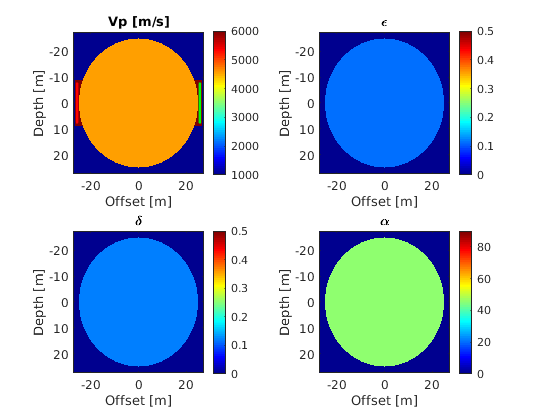

figure(11)
subplot(2,2,1)
imagesc(G.xx, G.zz, Vp'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('Vp [m/s]')
caxis([1000 6000])
hold on 
plot(Source.x,Source.z, '.r')
plot(Receiver.x,Receiver.z, '.g')

subplot(2,2,2)
imagesc(G.xx, G.zz, Epsilon'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\epsilon')
caxis([0 0.5])

subplot(2,2,3)
imagesc(G.xx, G.zz, Delta'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\delta')
caxis([0 0.5])

subplot(2,2,4)
imagesc(G.xx, G.zz, Alfa'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\alpha')
caxis([0 90])

## Compute traveltimes with FSM2DTTI code

TTI = 1e20*ones(G.nx, G.nz, length(Source.x)); 

tic
for i = 1:25:length(Source.x)
    S = zeros(1,3);
    S(1) = Source.x(i);
    S(3) = Source.z(i);
    tti  = FSM2DTTI(G, S, Vp, Epsilon, Delta, Alfa);    
    tti(~Tind) = 1e20; 
    TTI(:,:,i) = tti;
end
toc

Elapsed time is 51.719116 seconds.



TTI = TTI*1000;         % convert to micro sec
sTTI = TTI(:,:,151);    % single sensor
mTTI = min(TTI,[],3);   % multiple sensors 


## Plot traveltimes and wavefronts

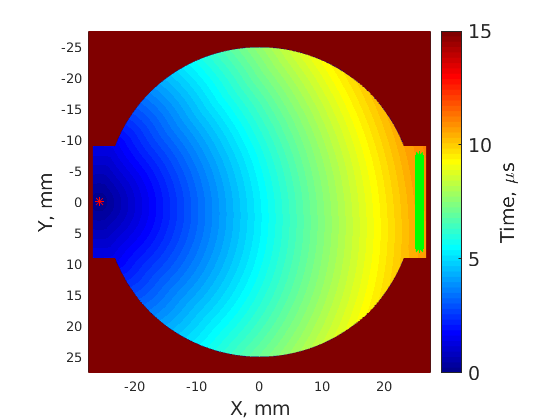

figure(12)
pcolor(G.xx, G.zz, sTTI'); 
shading interp
xlabel('X, mm', 'FontSize', 14);
ylabel('Y, mm', 'FontSize', 14);
set(gca, 'YDir', 'reverse');
hold on 
plot(Source.x(151), Source.z(151), '*r'); 
plot(Receiver.x, Receiver.z, '*g'); 
axis equal;
caxis([0 15])
axis([G.x0,G.mx,G.z0,G.mz])
colormap('jet')
c = colorbar('eastoutside', 'Fontsize', 14);
c.Label.String = 'Time, \mus';

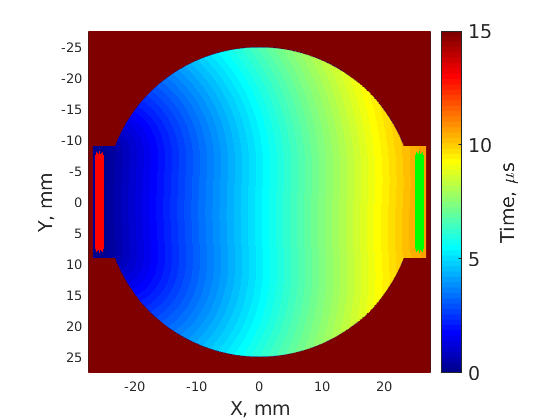



figure(18836)
pcolor(G.xx, G.zz, mTTI'); 
shading interp
hold on
%contour(G.xx, G.zz, tti', 'ShowText', 'on', 'Color', 'black')
xlabel('X, mm', 'FontSize', 14);
ylabel('Y, mm', 'FontSize', 14);
set(gca, 'YDir', 'reverse');
plot(Source.x, Source.z, '*r'); 
plot(Receiver.x, Receiver.z, '*g'); 
axis equal;
axis([G.x0,G.mx,G.z0,G.mz])
caxis([0 15])
colormap('jet')
c = colorbar('eastoutside', 'Fontsize', 14);
c.Label.String = 'Time, \mus';

%TT.true = (Receiver.x(1) - Source.x(1))/4500*1000*ones(size(Receiver.x)); 
TT.ssens = sTTI(Receiver.gx(1), Receiver.gz); 

Unable to perform assignment because dot indexing is not supported for variables of this type.

TT.msens = mTTI(Receiver.gx(1), Receiver.gz); 

figure(51654); 
plot(TT.ssens, 'r');
hold on 
plot(TT.msens, 'k');
%plot(TT.true, 'b') 


alpha = 0:5:90; 
for i=1:length(alpha)
    Alfa(CE.gxx,CE.gzz)  =  alpha(i);
    Alfa(Sind) = alpha(i);
    TT(i) = get_TT_model(G, Vp, Epsilon, Delta, Alfa, Tind, Source, Receiver)
end 


for i =1:19 
    ttm(i) = mean(TT(i).msens(1:25:301)); 
end




f = 1; % MHz
signal = ricker(f, G.tt); 
%signal = diff(signal,2)

%dtm = (TT.msens - mean(TT.msens)); 
%dts = (TT.ssens - mean(TT.ssens)); 

dtm = (TT.msens - 10.81); 
dts = (TT.ssens - 10.81); 

Ssignal = zeros(size(signal));
Msignal = zeros(size(signal));

for i=1:301
    ssignal = add_time_shift_fft(signal,dts(i)*100,f);
    Ssignal = Ssignal +ssignal; 
    msignal = add_time_shift_fft(signal,dtm(i)*100,f);
    Msignal = Msignal +msignal; 
end


figure(555163)
plot(signal)
hold on 
plot(Ssignal/301, 'r')
plot(Msignal/301, 'k')
